# **基于亮点模型的潜艇回波仿真（直线阵）**

***参考文献:***

***Simulation of Echoes from Submarine in Shallow  Waters   Rongguang Sun, Xin Ma, XiangIan Shu***

***Submarine Echo Simulation Method  Based on the Highlight Model Xiao Chen  Ya-an Li***

***基于亮点模型的潜艇回波仿真  何心怡 蒋兴舟 林建域***

***一种基于亮点模型的潜艇回波仿真  董仲臣 ,李亚安,陈 晓***

clc;clear;close all;
mycolor = setColor();

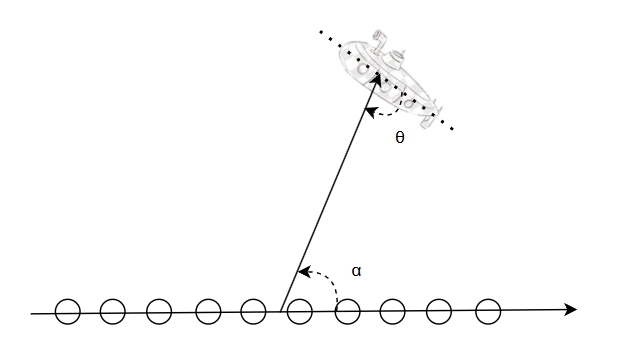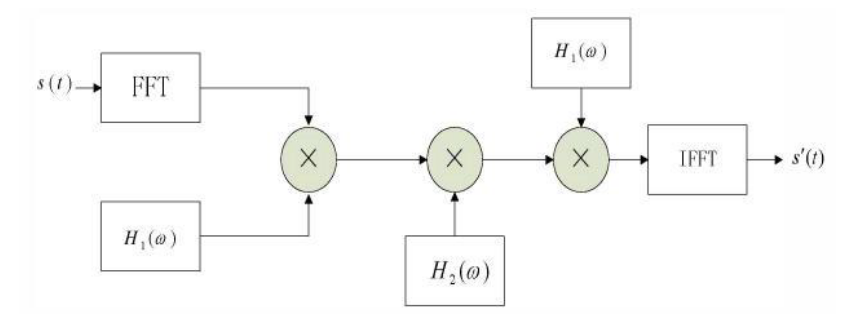

$\theta$和信道决定回波形状，$\alpha$为设定的波束角度

H1为信道转移函数，H2为潜艇亮点模型转移函数

## 1.仿真发射信号

%入射潜艇的角度
theta = 10;
fs = 5e3;
fc = 1.5e3;
% 定义时间参数
t = 0:1/fs:20 - 1/fs; % 时间向量，这里生成0到20秒的时间序列，采样间隔为1/fs
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
Ts = 1/fs;

###      CW信号：

   生成包络

% % 定义梯形脉冲参数
% Am = 1; % 幅度为1V
% %总脉宽120ms，上升10ms，下降10ms
% width = 100e-3; % 宽度为100ms
% rise_time = 10e-3; % 上升时间设为10ms
% fall_time = 10e-3; % 下降时间设为10ms
% a = genTrapSig(Am,t,width,rise_time,fall_time);
% 
% %绘制梯形脉冲信号
% figure;
% subplot(2,1,1);
% plot(t, a);
% xlabel('时间/ms');ylabel('幅度');title('信号的包络');
% grid on;
% axis([0,0.14,-6,6]);

发射的窄带脉冲

% wc = 2*pi*fc;
% P = a.*exp(j*wc*t);
% subplot(2,1,2);
% plot(t, real(P));
% xlabel('时间/ms');ylabel('幅度');title('发射的信号（实部）');
% grid on;
% axis([0,0.14,-6,6]);

###     LFM信号

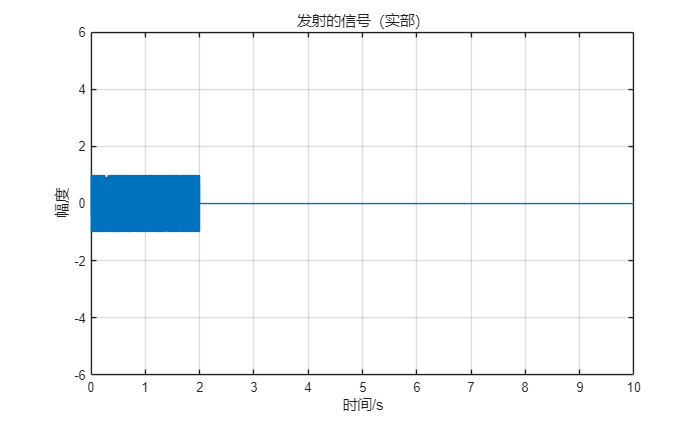

P = chirp(t,1.4e3,2,1.6e3);
P(round(fs*2)+1:end) = zeros(length(t)-fs*2,1);
matchedFilter = P(1:round(2*fs));
figure
plot(t, real(P));
xlabel('时间/s');ylabel('幅度');title('发射的信号（实部）');
grid on;
axis([0,10,-6,6]);

%[P_STFT ,F,T] = stft(P,fs,Window=kaiser(4050,5),OverlapLength=4000,FFTLength=8000);

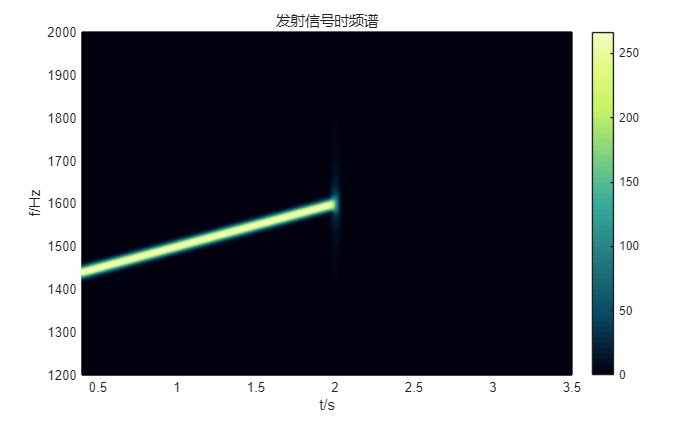

N = length(P);B = fs/2;
Sample = round(4*fs);
f = 0:fs/Sample:B-fs/Sample;
[P_STFT ,F,T] = spectrogram(P(1:round(4*fs)),1000,900,f,fs);
figure
mesh(T,F,abs(P_STFT));view(2);
axis([0.4,3.5,1200,2000]);
colormap(mycolor);xlabel('t/s');ylabel('f/Hz');
colorbar;
title('发射信号时频谱');

## 2.多普勒频移

    潜艇运动产生的多普勒频移：

v = 4.112;%潜艇运动速度8海里/h      0.514*8
c = 1530;
wh = 2*pi*5e3;%LFM频率
wd = 2*wh*v*cosd(theta)/c;%多普勒角频率
% wd = 2*wc*v*cosd(theta)/c;%多普勒角频率  CW

fprintf('多普勒频移为：%.2f Hz\n',wd);

多普勒频移为：166.30 Hz


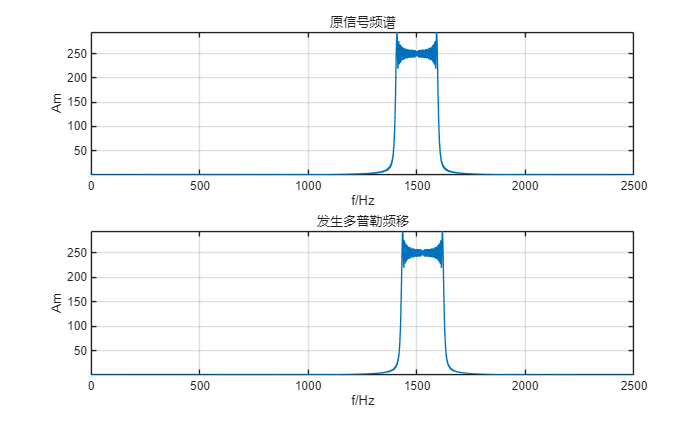


PWithDoppler = P.*exp(1j*wd*t);
Sample = round(4*fs);
f = -fs/2 : fs/Sample : fs/2 - (fs/Sample);
figure
subplot(2,1,1)
plot(f,abs(fftshift(fft(P(1:Sample)))));xlabel('f/Hz');ylabel('Am');title('原信号频谱');grid on;
axis([0,2500,-inf,inf]);
subplot(2,1,2)
plot(f,abs(fftshift(fft(PWithDoppler(1:Sample)))));xlabel('f/Hz');ylabel('Am');title('发生多普勒频移');grid on;
axis([0,2500,-inf,inf]);

[P_STFT ,F,T] = spectrogram(P(1:Sample),1000,900,f,fs);
figure
mesh(T,F,abs(P_STFT));view(2);
axis([0.4,3.5,1200,2000]);
colormap(mycolor);xlabel('t/s');ylabel('f/Hz');
colorbar;
title('发射信号发生多普勒频移');

P = PWithDoppler;%变量替换
clear PWithDoppler;
clear P_STFT T  F;

## 3.使用Bellhop计算脉冲响应

###     仿真深海场景

###     声速梯度

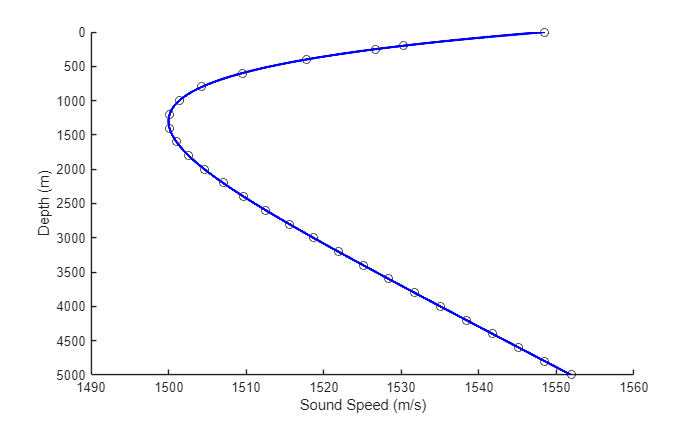

__________________________________________________________________
Munk profile, coherent
Frequency = 1500 Hz 
Number of media = 1 

    Spline approximation to SSP
    Attenuation units: dB/wavelength
    VACUUM

     z (m)     alphaR (m/s)      betaR       rho (g/cm^3)    alphaI        betaI 
    ( Number of pts = 51  Roughness =   0.00  Depth =  5000.00 ) 
      0.00       1548.52          0.00          1.00        0.0000        0.0000 
    200.00       1530.29          0.00          1.00        0.0000        0.0000 
    250.00       1526.69          0.00          1.00        0.0000        0.0000 
    400.00       1517.78          0.00          1.00        0.0000        0.0000 
    600.00       1509.49          0.00          1.00        0.0000        0.0000 
    800.00       1504.30          0.00          1.00        0.0000        0.0000 
   1000.00       1501.38          0.00          1.00        0.0000        0.0000 
   1200.00       1500.14          0.00          1.00        0.00

figure; 
bellhop Env\MunkB_Coh;clc;
plotssp('Env\MunkB_Coh');

根据声速梯度图，当深度为200m时，声速为1530m/s

###     传播损失

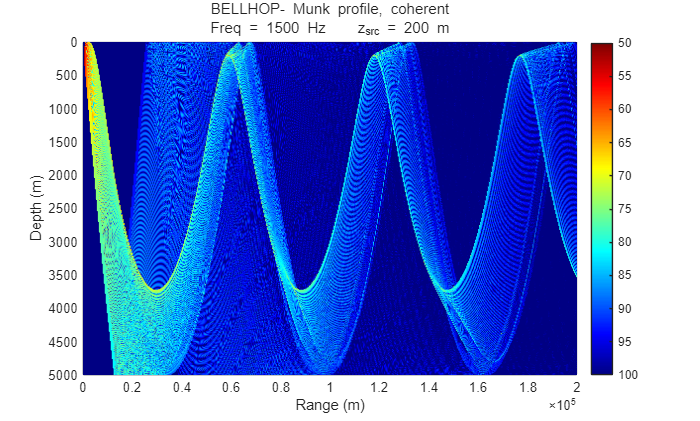

%计算传播损失
bellhop('Env\MunkB_Coh');
figure
plotshd('Env\MunkB_Coh.shd');

接收点深度300m，距离58954m

### 声线传播轨迹

bellhop('Env\MunkB_ray');
figure
global units;
units = 'km';%这样输出单位为km
plotray('Env\MunkB_ray.ray');

###     脉冲响应

bellhop计算脉冲响应

bellhop ('Env\MunkB_Arr');
figure
%plotarr('testEnvs\MunkB_Arr.arr',1,1,1);grid on;

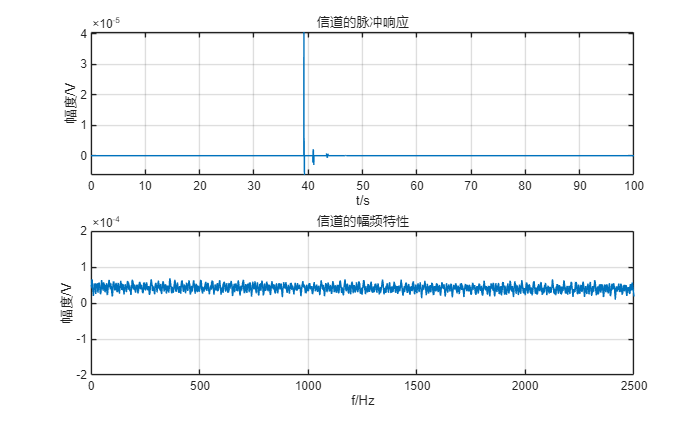

[ Arr, Pos ] = read_arrivals_asc( 'Env\MunkB_Arr.arr' );
Amp = real(Arr.A);%到达幅度
delay = Arr.delay;%到达时延


Amp_Delay = [delay;Amp];
Amp_Delay(:,all(Amp_Delay==0,1))=[]; %去掉0值
Amp_Delay=sortrows(Amp_Delay',1);  %按照时延从小到大排序
% figure
% stem(Amp_Delay(:,1),Amp_Delay(:,2));

t = 0:1/fs:100 - 1/fs; % 时间向量，这里生成0到100秒的时间序列，采样间隔为1/fs
IR = zeros(1,length(t));
%将bellhop得到的序列插入进单位脉冲响应中
delayIndex = round(Amp_Delay(:,1)./Ts);
for i = 1:length(delayIndex)
    IR(delayIndex(i)) = Amp_Delay(i,2);
end
TF1 = fftshift(fft(IR));
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
figure
subplot(2,1,1)
plot(t,IR);xlabel('t/s');ylabel('幅度/V');grid on;
axis([0,100,-inf,inf]);title('信道的脉冲响应');
subplot(2,1,2)
plot(f,abs(TF1));xlabel('f/Hz');ylabel('幅度/V');grid on;
axis([0,fs/2,-20e-5,20e-5]);title('信道的幅频特性');

信号经过信道

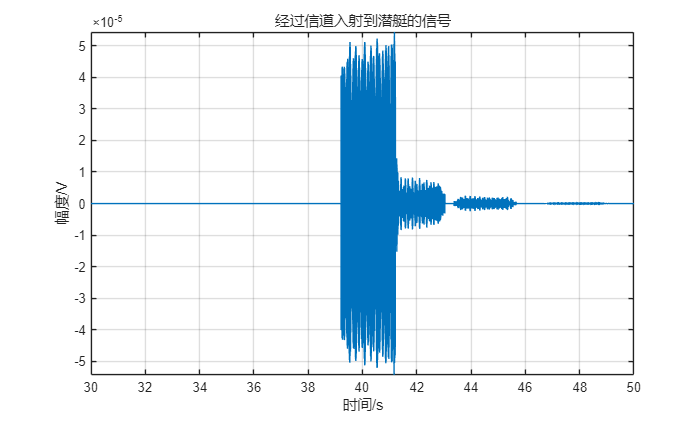

%PAfterChan = conv(real(IR),P,'same');
PAfterChan = conv(real(IR),P);
figure
plot(t,real(PAfterChan(1:N)));xlabel('时间/s');ylabel('幅度/V');grid on;
title('经过信道入射到潜艇的信号');axis([30,50,-inf,inf]);

P = PAfterChan(1:N);

## 4.每个亮点的时延

R为鱼雷与潜艇距离,即鱼雷与代表艇尾的亮点距离;0为照射角;表示该亮点与艇艉的距离

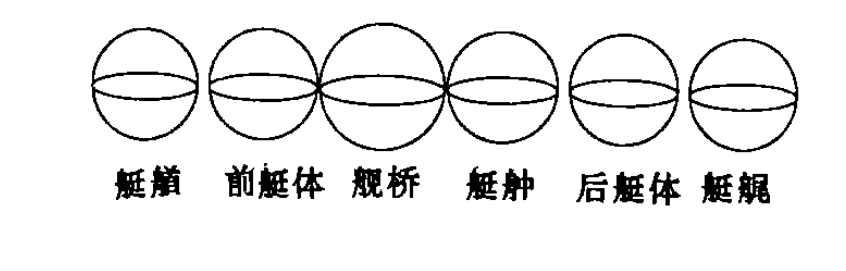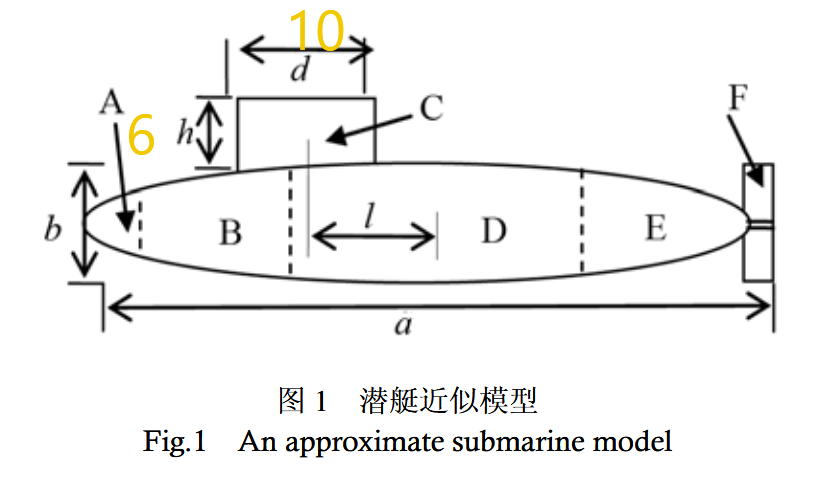

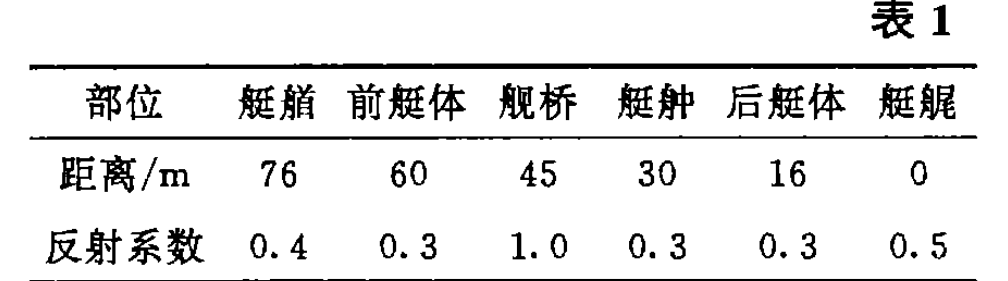

亮点模型各个亮点的时延：$\tau_i = \frac{2\sqrt{(L_icos\theta)^2+(L_isin\theta)^2}}{c}$

此公式时总的时延公式

tauHighLight = zeros(6,1);
L = zeros(6,1);  %L存放亮点与艇艇的距离
L = [76,   60,     45,   30,   16,   0]; 
R = 58954;    %两者的距离
c = 1530;    %深度1000m 声速1500m/s

for j = 1:6
     term1 = (L(j)*cosd(theta)).^2;
     term2 = (L(j)*sind(theta))^2;
     numerator = 2*sqrt(term1 + term2);
     tauHighLight(j) = numerator/c;  %此时c为1500m/s 深度1000m
end

  亮点的时延

for i = 1:6 
    fprintf('%f s\n', tauHighLight(i));
end

0.099346 s
0.078431 s
0.058824 s
0.039216 s
0.020915 s
0.000000 s


## 5.计算亮点的子回波幅度

计算每个亮点的半径

% 定义距离和反射系数
b = [0.4, 0.3, 1.0, 0.3, 0.3, 0.5];
r = [7,7,8,7,7,7];

### 计算隐蔽系数

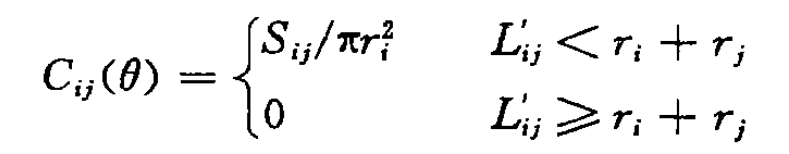

计算Sij

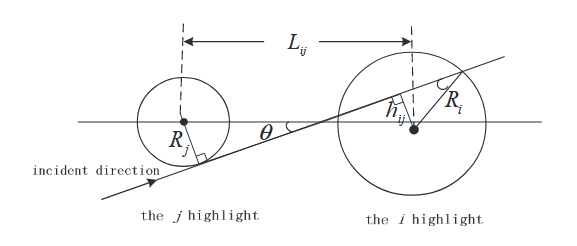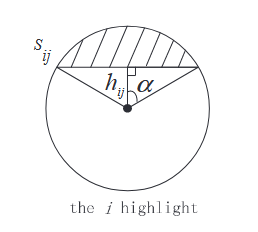

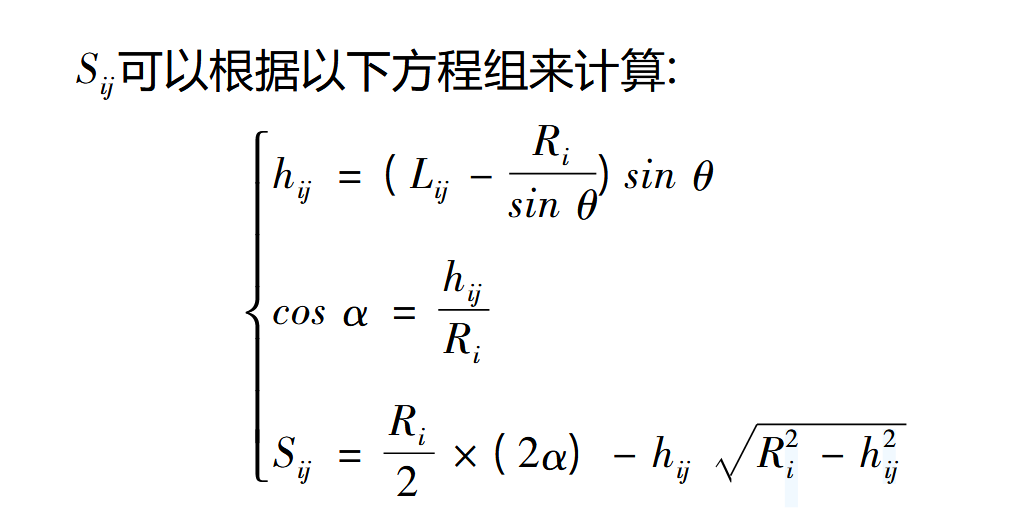此处面积的计算存在错误

L_ij = zeros(6,6);
h_ij = zeros(6,6);
S_ij = zeros(6,6);
%gamma为图中的alpha
for i =1:6
    for j = 1:6
        L_ij(i,j) =abs( L(j) - L(i) );
        h_ij(i,j) = (L_ij(i,j) - r(i)/(sind(theta)+eps) ).*sind(theta);
        gamma = acos(h_ij(i,j)/r(i));
        S_ij(i,j) = r(i).^2 /2.*(2*gamma) - h_ij(i,j)*sqrt(r(i).^2 - h_ij(i,j).^2);
    end
end


任何一个亮点最多可能被5个亮点所遮挡，最多也就有5个隐蔽系数,那么亮点i的隐蔽系数等于其中最大的隐蔽系数:

一个亮点的实际反射系数为

则一个亮点在考虑有隐蔽情况下其目标强度为

该亮点子回波的幅度为

% 计算隐蔽系数
C_ij = zeros(6,6);
for i = 1:6
    for j = 1:6
        if abs( L_ij(i,j)*sind(theta) ) < r(i) + r(j)   %传播方向上的投影长度小于亮点半径之和
            C_ij(i, j) = S_ij(i,j)/(pi  *  (r(i).^2)  ); 
        else
            C_ij(i, j) = 0;
        end
    end
end
C_ij(1:size(C_ij,1)+1:end) = 0;  % 将 C_ij 的对角元素设为 0,因为隐蔽系数的计算不考虑亮点自己本身
% 计算每个亮点的实际反射系数
B = zeros(1, 6);
for i = 1:6
    C(i) = max(C_ij(i, :));
    B(i) = b(i) .* (1 - C(i));
    % 计算目标强度
    TS(i) = 10 * log10(r(i).^2 / 4) + 10 * log10(B(i));
    
    % 计算亮点子回波幅度
    A(i) = 10.^(TS(i) / 20);
end

亮点的回波幅值

% 输出结果
disp(A);

    0.8306    0.6868    1.3017    0.6536    0.6536    0.9287



## 6.入射产生相位跳变

跳变相位应该是一个0~2$\pi$的随机变量，在这里设定成180°

phi = pi;%假设相位跳变180°

## 7.计算回波

### 计算亮点模型的转移函数

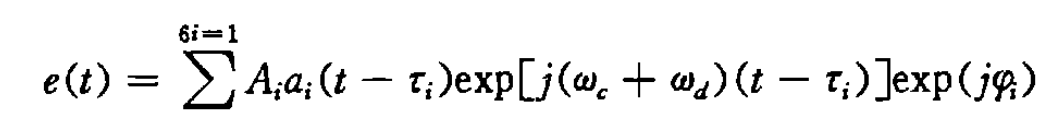

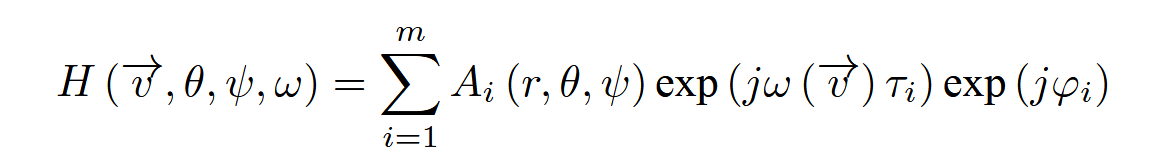

此公式为亮点模型的转移函数，将之前的计算带入

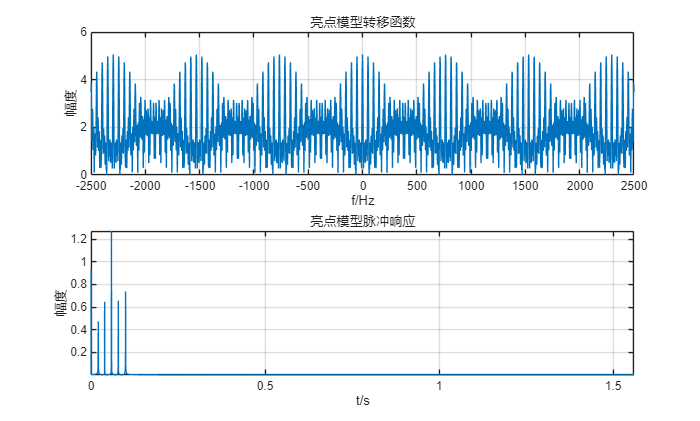

%计算亮点模型的转移函数
highlightTF = zeros(6,N);
temp = zeros(1,N);
for i = 1:6%计算每个部位的转移函数
    highlightTF(i,:) = A(i)*exp(-1j*(2*pi*f)*tauHighLight(i)).*exp(1j*phi);
end
TF2 = sum(highlightTF,1);%将转移函数相加
figure
subplot(2,1,1);
plot(f,abs(TF2));xlabel('f/Hz');ylabel('幅度');grid on;title('亮点模型转移函数');
axis(-fs/2,fs/2,0,inf);
IR_Highlight = ifft(TF2);
subplot(2,1,2);
time = 1.56;
plot(t,abs(IR_Highlight));xlabel('t/s');ylabel('幅度');grid on;title('亮点模型脉冲响应');
axis([0,time,-inf,inf]);

PAfterRef = ifft(fftshift(fft(P)).*TF2);%逆变换得到时域的波形
for i = 1:6
    PRef(i,:) = ifft(fftshift(fft(P)).*highlightTF(i,:));%每个部位的反射信号
end

各个部位亮点的回波

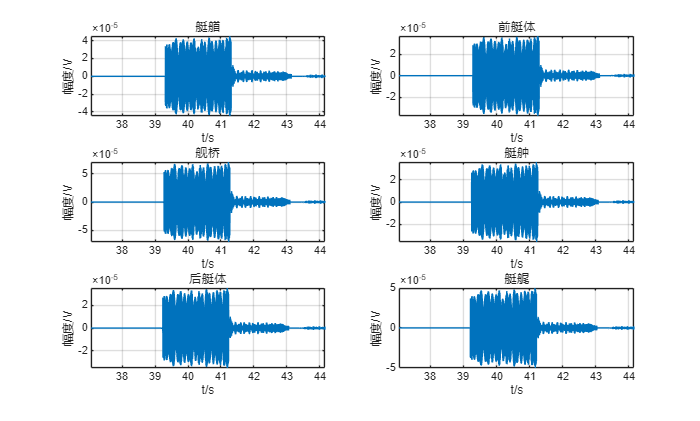

scale = [37.05 44.16];
helpViewEveryPart(PRef,t,[scale,-inf,inf]);

潜艇的回波

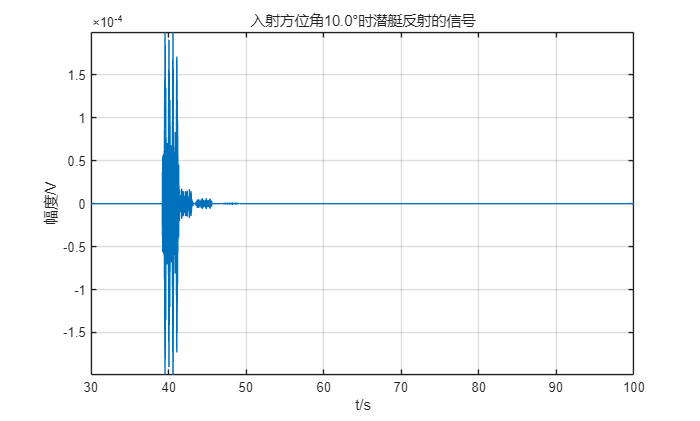

figure
plot(t,real(PAfterRef));xlabel('t/s');ylabel('幅度/V');grid on;
title(sprintf('入射方位角%.1f°时潜艇反射的信号', theta));axis([30,100,-inf,inf]);

e = PAfterRef;
clear PAfterRef;

## 8.信号返回发射点：

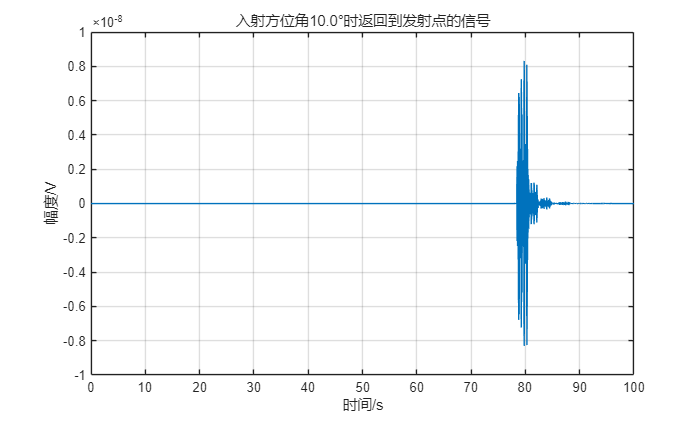

eAfterChan = ifft((fftshift(fft(e)).*TF1));
figure
plot(t,real(eAfterChan));xlabel('时间/s');ylabel('幅度/V');grid on;
title(sprintf('入射方位角%.1f°时返回到发射点的信号', theta));

s = eAfterChan;%交换变量
clear eAfterChan;

## 9.波束形成

接收到的信号波束形成

考虑阵列情况

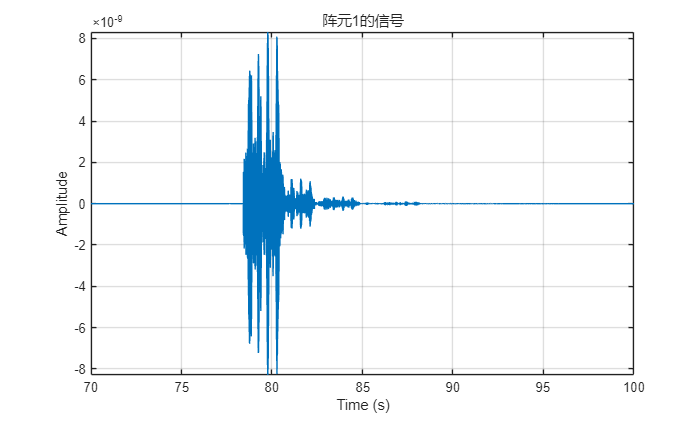

d = 1; % 阵元间距（10m长的线阵，共10个元素）
N = 10; % 阵元数量
angles = -90:10:90; % 角度范围 -90° 到 90°
alpha = 60;%阵列的接收角度（0°~180°）
%% 仿真阵元域数据
t_total = t; % 总时间向量
L = length(t_total);
fft_len = 2^nextpow2(L); % FFT长度
element_signals = zeros(N, length(t_total)); % 初始化阵元信号矩阵
alpha = alpha-90;
for i = 1:N
    delay = -(i-1)*d*sind(alpha)/c; % 计算时延
    delay_samples = round(delay * fs); % 时延转换为样本数
    element_signals(i,:) = applyDelay(s, delay_samples);
end
figure;
plot(t,real(element_signals(1,:)));
title('阵元1的信号');axis([70,100,-inf,inf]);xlabel('Time (s)');ylabel('Amplitude');grid on;

每个阵元接收的信号

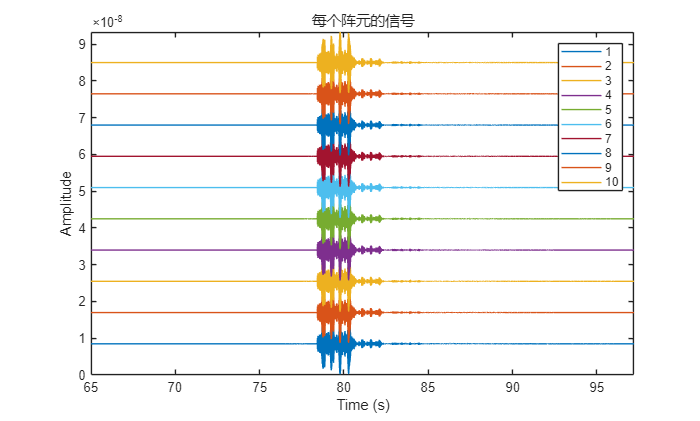

figure;
bias =8.5e-9;
scale = [65 97.2];
plot(t,real(element_signals).'+[1:N]*bias);
title('每个阵元的信号');axis([scale,0,inf]);xlabel('Time (s)');ylabel('Amplitude');
legend('1','2','3','4','5','6','7','8','9','10');

每个角度波束信号

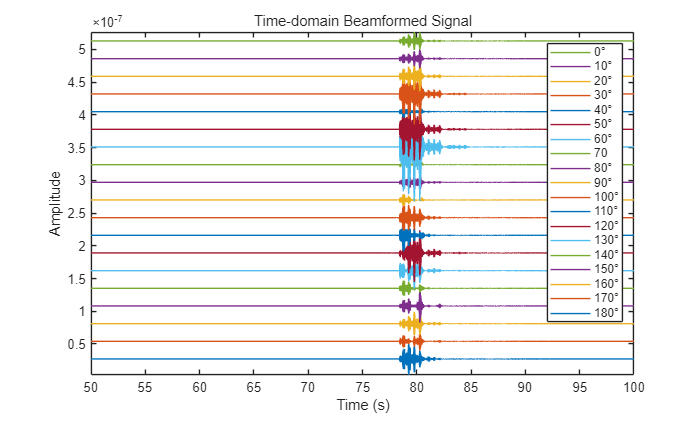

%% 时延波束形成
beamformed_signals_time_domain = zeros(length(angles), L); % 初始化时域波束形成信号矩阵
for j = 1:length(angles)
    alpha = angles(j);
    beamformed_signal_time_domain = zeros(1, L);
    for i = 1:N
        delay = (i-1)*d*sind(alpha)/c; % 计算时延
        delay_samples = round(delay * fs); % 时延转换为样本数
        element_signal = applyDelay(element_signals(i,:), delay_samples);
        beamformed_signal_time_domain = beamformed_signal_time_domain + element_signal;
    end
    beamformed_signals_time_domain(j,:) = beamformed_signal_time_domain(1:L); % 截取有效部分
end

% 输出波束域数据
figure;
bias = 1.35e-8;
helpViewBeamInEveryDegree(t_total,beamformed_signals_time_domain,angles,bias);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-domain Beamformed Signal');

clear delay element_signal beamformed_signal_time_domain
%save('TD.mat', 't_total', 'beamformed_signals_time_domain');
%保存

60°波束接收信号的时频

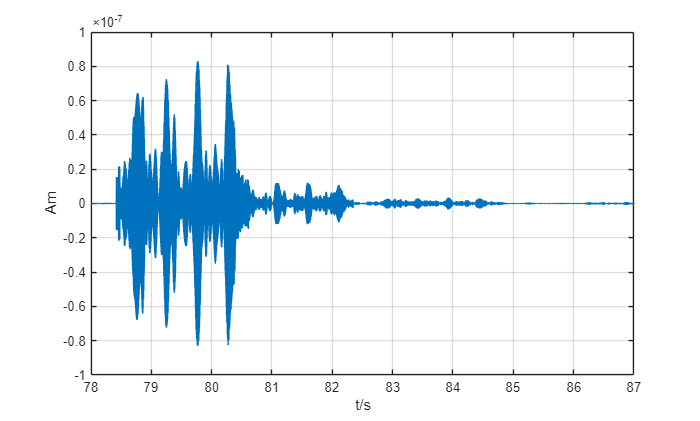

SigBeam = beamformed_signals_time_domain(7,:);

Sample = round((87-78)*fs);     %选取77~87s 10s
f = 0 : fs/Sample : fs/2 - (fs/Sample);
Sig=SigBeam(round(78*fs)+1:round(87*fs));
t = 78:1/fs:87-1/fs;
figure
plot(t,Sig);xlabel('t/s');ylabel('Am');grid on;

[beam60 ,F,T] = spectrogram(SigBeam,20000,19000,f,fs);

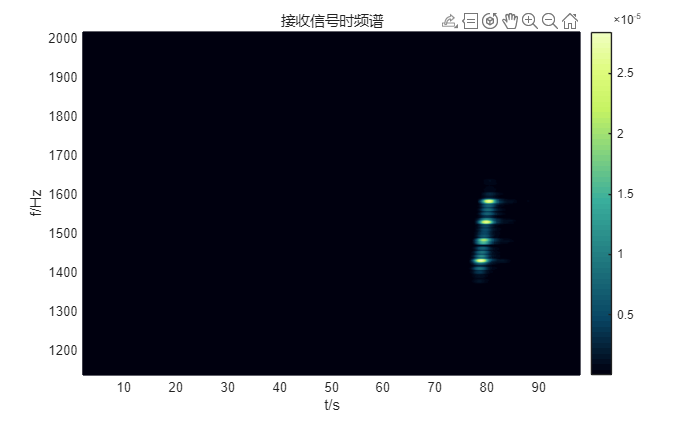

figure
%T = T + ones(1,length(T))*77;
mesh(T,F,abs(beam60));view(2);
axis([-inf,inf,1200,2000]);colorbar;colormap(mycolor);
xlabel('t/s');ylabel('f/Hz');
title('接收信号时频谱');

## 10.匹配滤波

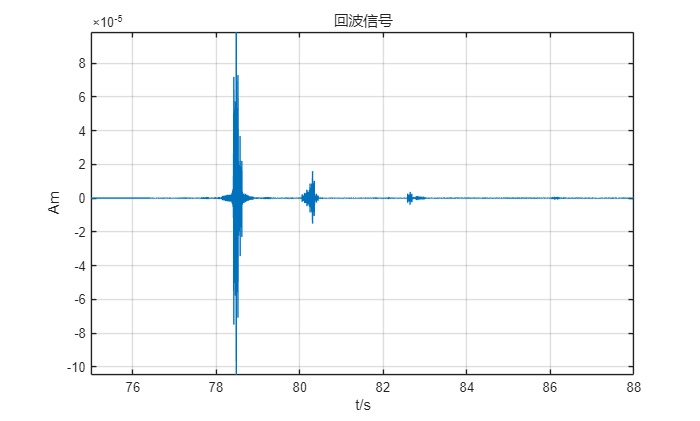

[r,lags] = xcorr(SigBeam ,matchedFilter);
idx = round(find(lags>=0));
r = r(idx:end);
lags = lags(idx:end);
figure
plot(lags*(1/fs),real(r));xlabel('t/s');ylabel('Am');grid on;title('回波信号');
scale = [60 76];
t = 0:1/fs:100-1/fs;

axis([75,88,-inf,inf]);

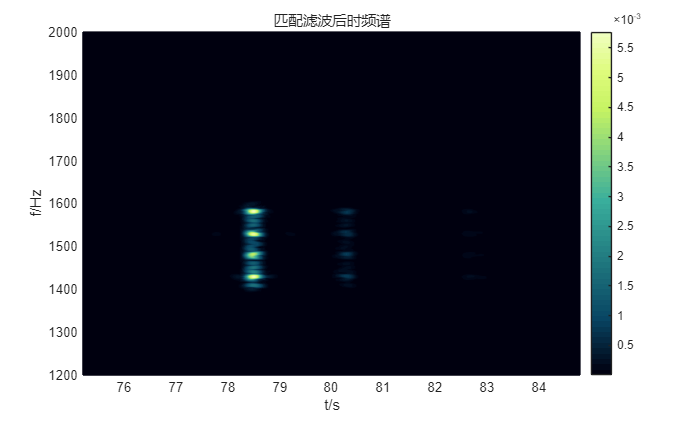

buffer = r(round(75*fs):round(85*fs)-1);
[R,F,T] = spectrogram(buffer,2000,1900,f,fs);
figure
%T = T + ones(1,length(T))*77;
T = T+75*ones(1,length(T));
mesh(T,F,abs(R));view(2);
axis([-inf,inf,1200,2000]);colorbar;colormap(mycolor);
xlabel('t/s');ylabel('f/Hz');
title('匹配滤波后时频谱');